# DoE Generator Live Script

## Create structure listing identification parameters

The Fouling Model Simulation Code is supplied with 3 structures which configure the model for each simulation run:

- ***BoundCond***: supplies the boundary conditions for the simulation.

- ***ModelPara***: defines the identification para                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        meter settings for the current simulation.

- ***Options***: enables or disables the soot deposit and removal mechanisms and the HC and water condensation and evaporiasation models.

Note, distributed parameters are represented as B-splines for compactness and are automatically converted to lookup tables by the code. 

## Configure duct geometry and number of tubes

clear;
clc;

DuctGeometry = "Circle";    % Duct interior geometry
InteriorDia = 4.5;     % Clean tube interior (or hydraulic) diameter [mm]
NumberOfTubes = 35;   % Number of tubes
TubeLength = 185;      % Length of tube [mm]

## Configure Parameters or Boundary Conditions to be Estimated from Data

F(1).Name = "fRegMP";               % Friction factor regression parameters
F(1).Units = "[]";
F(1).Fixed = true;                  % Fixed parameter 
F(1).Lo = [ 0.30, -1.10, 0.35 ];    
F(1).Hi = [ 0.80, -0.50, 0.95];
F(1).Sz = [1,3];
F(1).Type = "Parameter";
F(1).Spline = struct.empty( 0, 5 );
F(2).Name = "NuRegMP";              % Nusselt number regression parameters
F(2).Units = "";
F(2).Fixed = true;                  % Fixed parameter  
F(2).Lo = [ 0.50, 0.30, 0.80];  
F(2).Hi = [ 1.10, 0.90, 1.60 ];
F(2).Sz = [1,3]; 
F(2).Type = "Parameter";
F(2).Spline = struct.empty( 0, 5 ); 
F(3).Name = "Distr_Kf";                      % friction factor gain
F(3).Units = "";
F(3).Fixed = false;                         % Fixed parameter
F(3).Lo = 0.75;
F(3).Hi = 1.25;
F(3).Sz = [ 9, 9 ]; 
F(3).Type = "Parameter";
F(3).Spline.M = [3, 3];                    % Tensor product spline parameters
F(3).Spline.K = [1, 1];
F(3).Spline.X = [ "mg_dot", "T_g_in"];     % EGR mass flow and Inlet gas temperature.
F(3).Spline.Xlo = [10, 200];
F(3).Spline.Xhi = [100, 350];
F(4).Name = "Distr_KNu";                      % Nusselt number gain
F(4).Units = "";
F(4).Fixed = false;                         % Fixed parameter
F(4).Lo = 0.75;
F(4).Hi = 1.25;
F(4).Sz = [11, 11]; 
F(4).Type = "Parameter";
F(4).Spline.M = [4, 4];                    % Tensor product spline parameters
F(4).Spline.K = [1, 1];
F(4).Spline.X = [ "mg_dot", "T_g_in"];     % EGR mass flow and Inlet gas temperature.
F(4).Spline.Xlo = [10, 200];
F(4).Spline.Xhi = [100, 350];

## Set number of computational cells for the simulation

The more cells you have the more accurate the simulation results, at the expense of computational expense. In our experience, 10 - 20 is a good compromise.

NumComputationalCells = 10;

## Define the ECOMO User Interface Object

UseParallel = true;
obj = ECOMOuserInterface( "TubeDia", InteriorDia, "TubeLen", TubeLength, "NumTubes", NumberOfTubes,...
    "TubeGeo", DuctGeometry, "Parallel", UseParallel, "Clean", true );

## Set the exploration rate multiplier. Provides the user with an easy way of increasing or decreasing the amount of exploration versus exploitation. The larger the multiplier the more explanatory the search.

ExplorationMult = 1;
obj = obj.setExploreGain( ExplorationMult );

## Set cost function:

###         Pressure           $\longrightarrow$ cost function is a function of delta pressure measure only

###         Temperature     $\longrightarrow$ cost function is a function of outlet temperature measure only

###         Combined         $\longrightarrow$ cost function is a function of both pressure and temperature measures.

CostFcn = "Combined";
obj = obj.setCostFcn( CostFcn );

## Load the Identification Data and PN Distribution Data

%-----------------------------------------------------------------------
% Define name of variable containing identification data
%-----------------------------------------------------------------------
StructName = "CharTVars3";
%--------------------------------------------------------------
% Load the identification data
%--------------------------------------------------------------
obj.loadIdentificationData( StructName );
%--------------------------------------------------------------
% Load the PN distribution data
%--------------------------------------------------------------
obj.loadPNdistDataFile();

## Load the ECOMO model initialisation file

obj.initialisation();

## Perform the Identification & Plot the Results

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis inp

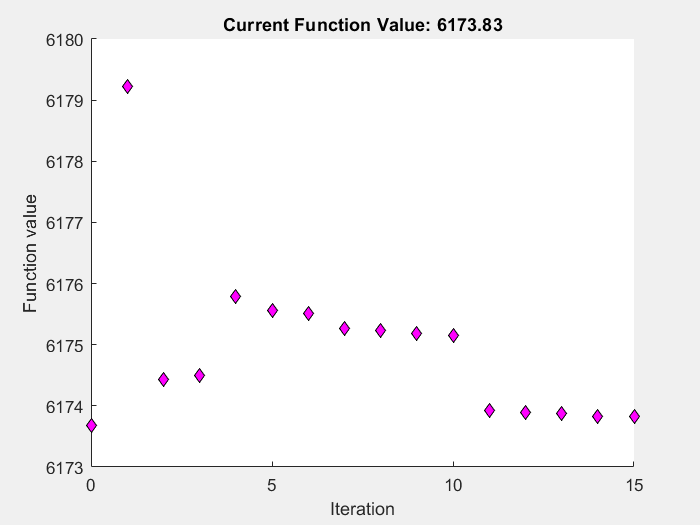

run----------------time sereis input: time step:  100 / 659 ----------------
run----------------time sereis input: time step:  200 / 659 ----------------
run----------------time sereis input: time step:  300 / 659 ----------------
run----------------time sereis input: time step:  400 / 659 ----------------
run----------------time sereis input: time step:  500 / 659 ----------------
run----------------time sereis input: time step:  600 / 659 ----------------


DesignSize = [ 500, 150 ];
Seq = { ["fRegMP", "NuRegMP"], [ "Distr_Kf", "Distr_KNu"] };
DataBudget =  25;                   % Number of Bayesian Optimisation iterations
ConvCounterLimit = 2;              % Number of consecutive identical results for early conversion
obj = obj.cleanCoolerID( F, Seq, DesignSize, DataBudget, ConvCounterLimit );

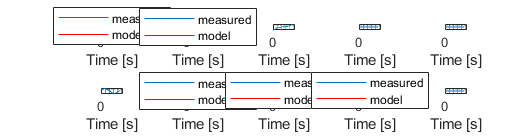

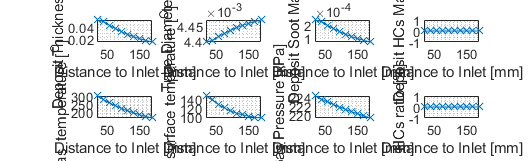

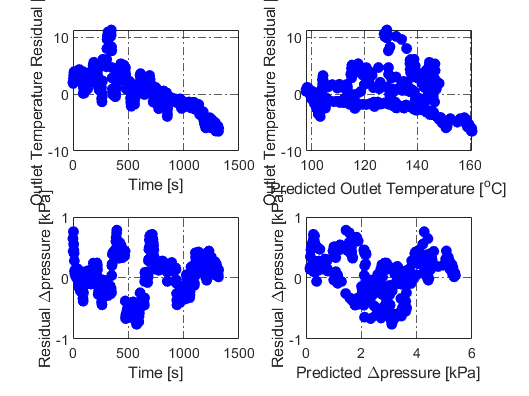

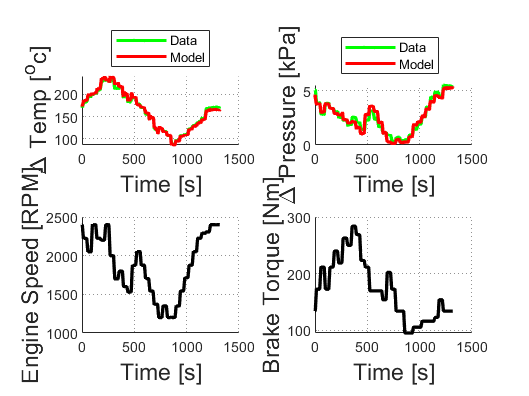

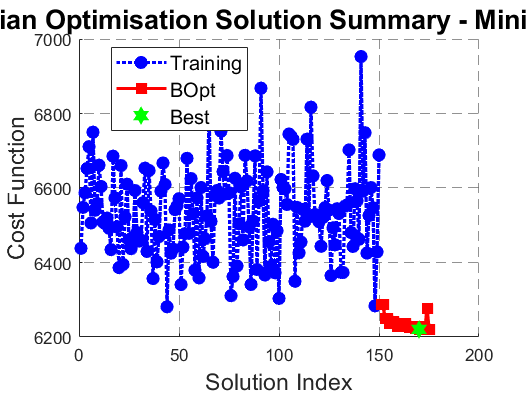

obj.plot;

%-----------------------------------------------------------------------
% Export the results to the workspave
%-----------------------------------------------------------------------
FM = obj.exportParameters();

## Tabulate the Identified Nu Parameters $N_u =A\ldotp R_e^C \ldotp P_r^D$

Idx = matches( [ F.Name ], "NuRegMP" );
if any( Idx )
    NuReg = FM.ModelPara.NuRegMP;
    Lo = F( Idx ).Lo;
    Hi = F( Idx ).Hi;
    Nu = table( Lo.', NuReg.', Hi.' );
    Nu.Properties.RowNames = [ "A", "C", "D"];
    Nu.Properties.VariableNames = [ "Low", "Value", "High" ];
    disp( Nu )
end

         Low     Value     High
         ___    _______    ____

    A    0.5    0.57606    1.1 
    C    0.3    0.52409    0.9 
    D    0.8        0.8    1.6 



## Tabulate the Identified $f$ Parameters:

## $f=\frac{D_1 }{R_e },R_e <2300$ (Laminar Flow)

## $f=D_2 \ldotp R_e^E$, $R_e \in \left\lbrack 4000,20000\right\rbrack$ (Turbulent Flow)

Idx = matches( [ F.Name ], "fRegMP" );
if any( Idx )
    Darcyf = FM.ModelPara.fRegMP;
%     Darcyf = 
    Lo = F( Idx ).Lo;
    Hi = F( Idx ).Hi;
    Darcyf = [ Darcyf(2,:) Darcyf(3,1)];
    f = table( Lo.', Darcyf.', Hi.' );
    f.Properties.RowNames = [ "D_2", "E", "D_1"];
    f.Properties.VariableNames = [ "Low", "Value", "High" ];
    disp( f )
end

           Low      Value      High
           ____    ________    ____

    D_2     0.3     0.69561     0.8
    E      -1.1    -0.92103    -0.5
    D_1    0.35        0.35    0.95



## Plot the $K_{N_u }$ Surface

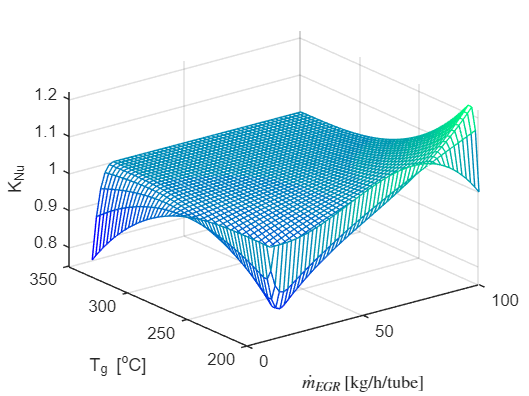

Idx = matches( [ F.Name ], "Distr_KNu" );
if any( Idx )
    T = obj.DoEgenerator.Bspline{ "Distr_KNu", "Object" };
    if iscell( T )
        T = T{ : };
    end
    %------------------------------------------------------------------------------
    % Assign the surface coefficients
    %------------------------------------------------------------------------------
    Alpha = table2array( obj.DoEgenerator.DesignInfo("Distr_KNu", "Coefficients") );
    if iscell( Alpha )
        Alpha = Alpha{ : };
    end
    T = T.setAlpha( obj.EcomoInterface.B.Xbest( Alpha ) );
    %------------------------------------------------------------------------------
    % Assign the knot sequence
    %------------------------------------------------------------------------------
    Knots = table2array( obj.DoEgenerator.DesignInfo("Distr_KNu", "Knots") );
    if iscell( Knots )
        Knots = Knots{ : };
    end
    Knots = obj.EcomoInterface.B.Xbest( Knots );
    Knots = T.convertKnotSequences( Knots );
    T = T.setKnotSequences( Knots );
    AxMesh = T.mesh( 50 );
    AxMesh.XLabel.Interpreter = "latex";
    AxMesh.XLabel.String = "$\dot{m}_{EGR}$ [kg/h/tube]";
    AxMesh.YLabel.String = "T_g [^oC]";
    AxMesh.ZLabel.String = "K_{Nu}";
end

## Plot the $K_f$ Surface

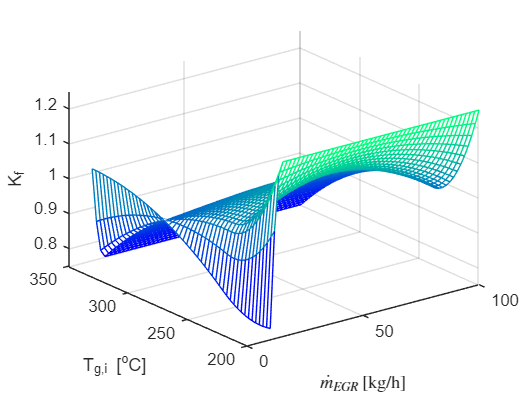

Idx = matches( [ F.Name ], "Distr_Kf" );
if any( Idx )
    T = obj.DoEgenerator.Bspline{ "Distr_Kf", "Object" };
    if iscell( T )
        T = T{ : };
    end
    %------------------------------------------------------------------------------
    % Assign the surface coefficients
    %------------------------------------------------------------------------------
    Alpha = table2array( obj.DoEgenerator.DesignInfo("Distr_Kf", "Coefficients") );
    if iscell( Alpha )
        Alpha = Alpha{ : };
    end
    T = T.setAlpha( obj.EcomoInterface.B.Xbest( Alpha ) );
    %------------------------------------------------------------------------------
    % Assign the knot sequence
    %------------------------------------------------------------------------------
    Knots = table2array( obj.DoEgenerator.DesignInfo("Distr_Kf", "Knots") );
    if iscell( Knots )
        Knots = Knots{ : };
    end
    Knots = obj.EcomoInterface.B.Xbest( Knots );
    Knots = T.convertKnotSequences( Knots );
    T = T.setKnotSequences( Knots );
    AxMesh = T.mesh( 50 );
    AxMesh.XLabel.Interpreter = "latex";
    AxMesh.XLabel.String = "$\dot{m}_{EGR}$ [kg/h]";
    AxMesh.YLabel.String = "T_{g,i} [^oC]";
    AxMesh.ZLabel.String = "K_f";
end